rootFolder = 'color';
srcFiles = dir('color/*');

for i = 3:length(srcFiles)
    categories{1,i-2}=srcFiles(i).name; %Read different categories of items
end
imds = imageDatastore(fullfile(rootFolder, categories), 'LabelSource', 'foldernames');
[imds70,imdsv15,imdst15] = splitEachLabel(imds,0.7,0.15);
%Split Training data as 70%, Validation data as 15% and Testing data as 15%

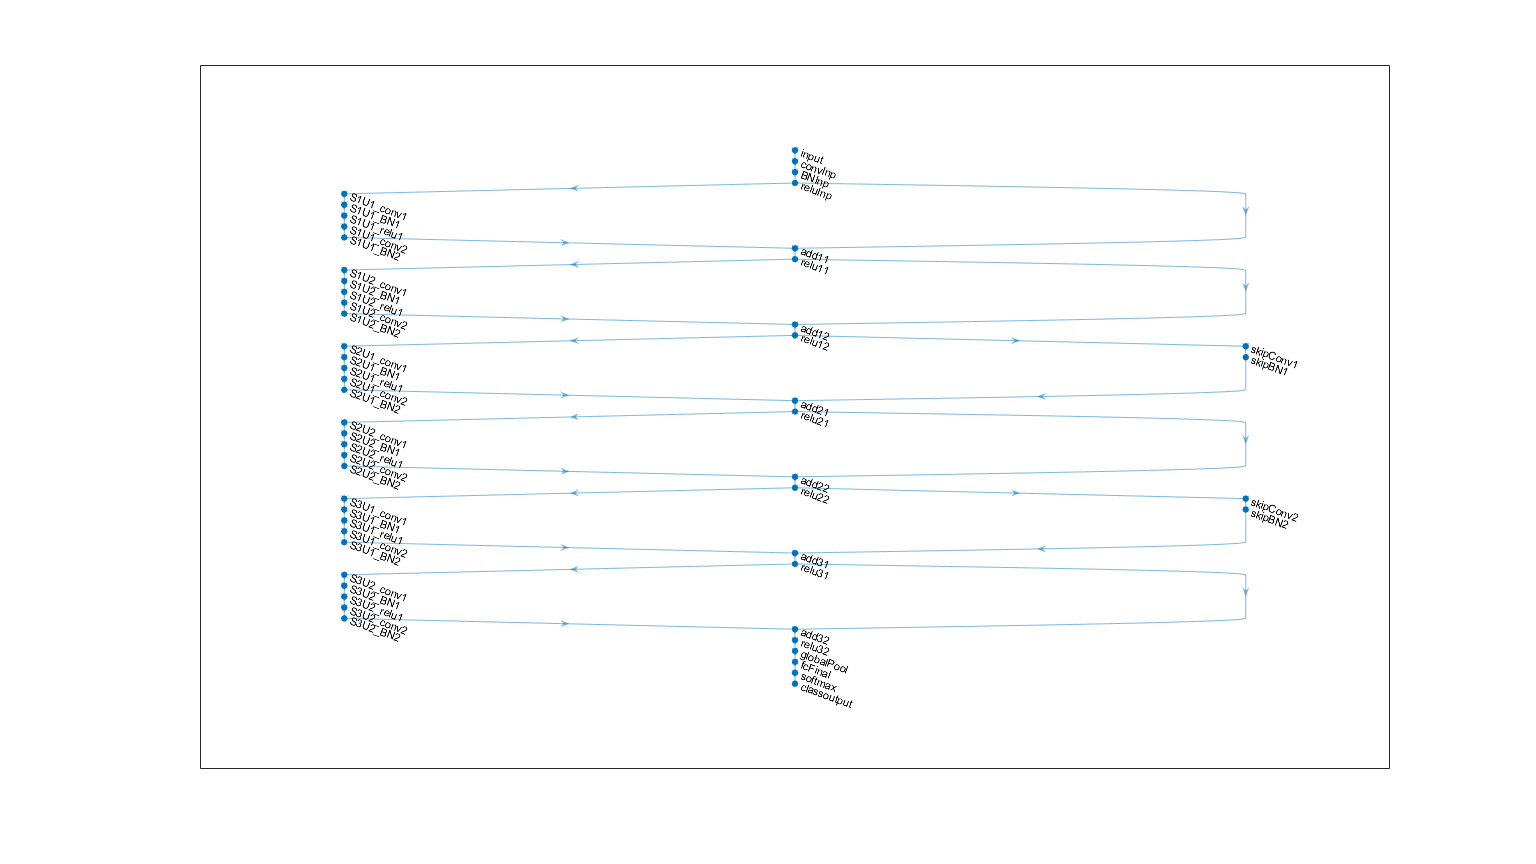

numUnits = 6;
netWidth = 32;
lgraph = residualgraph(netWidth,numUnits);
figure('Units','normalized','Position',[0.1 0.1 0.8 0.8]);
plot(lgraph)

checkpointPath = pwd;
miniBatchSize = 64;
learnRate = 0.1*miniBatchSize/128;
%load('net_checkpoint__43882__2019_01_27__13_10_25.mat','net')
options = trainingOptions('sgdm', ...
    'InitialLearnRate',learnRate, ...
    'MaxEpochs',87, ... %set max epoch the network was trained for 87 epochs
    'MiniBatchSize',miniBatchSize, ...
    'Shuffle','every-epoch', ...
    'Plots','training-progress', ...
    'Verbose',false, ...
    'ValidationFrequency',500, ...
    'LearnRateSchedule','piecewise', ...
    'ValidationData',imdsv15,...
    'LearnRateDropFactor',0.1, ...
    'LearnRateDropPeriod',60,...
    'ExecutionEnvironment','multi-gpu', ... %set to multi-gpu, other options : cpu, gpu
    'CheckpointPath',checkpointPath);

doTraining = false; %decide to train or not
if doTraining
    trainedNet = trainNetwork(imds70,lgraph,options);
    save('trainedNet','trainedNet')
else
    load('trainedNet.mat','trainedNet')
end

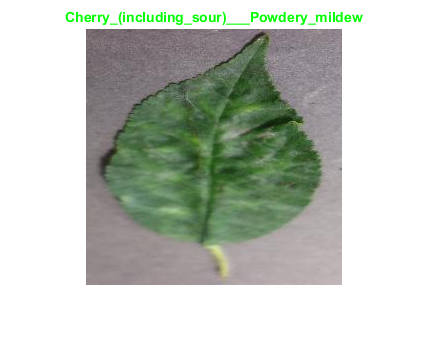

testdata=imdst15; %set testing data
labels = classify(trainedNet, testdata);
T = countEachLabel(testdata);
t15size=sum(T.Count);
%randomly test 1 image.
ii = randi(t15size);
im = imread(testdata.Files{ii});
imshow(im);
if labels(ii) == testdata.Labels(ii)
   colorText = 'g'; 
else
    colorText = 'r';
end
title(char(labels(ii)),'Color',colorText);

confMat = confusionmat(testdata.Labels, labels); %test all test images
confMat = confMat./sum(confMat,2);
mean(diag(confMat))

ans = 0.8998

for i =1:size(confMat,1)

    recall(i)=confMat(i,i)/sum(confMat(i,:));
end
recall(isnan(recall))=[];

Recall=sum(recall)/size(confMat,1);

%%% precision
for i =1:size(confMat,1)
    precision(i)=confMat(i,i)/sum(confMat(:,i));
end

Precision=sum(precision)/size(confMat,1)

Precision = 0.9044

%%% F-score

F_score=2*Recall*Precision/(Precision+Recall)

F_score = 0.9021